**Fit our model to the data from Dai, et.al., 2016.**

**For Figure 5b and c.**

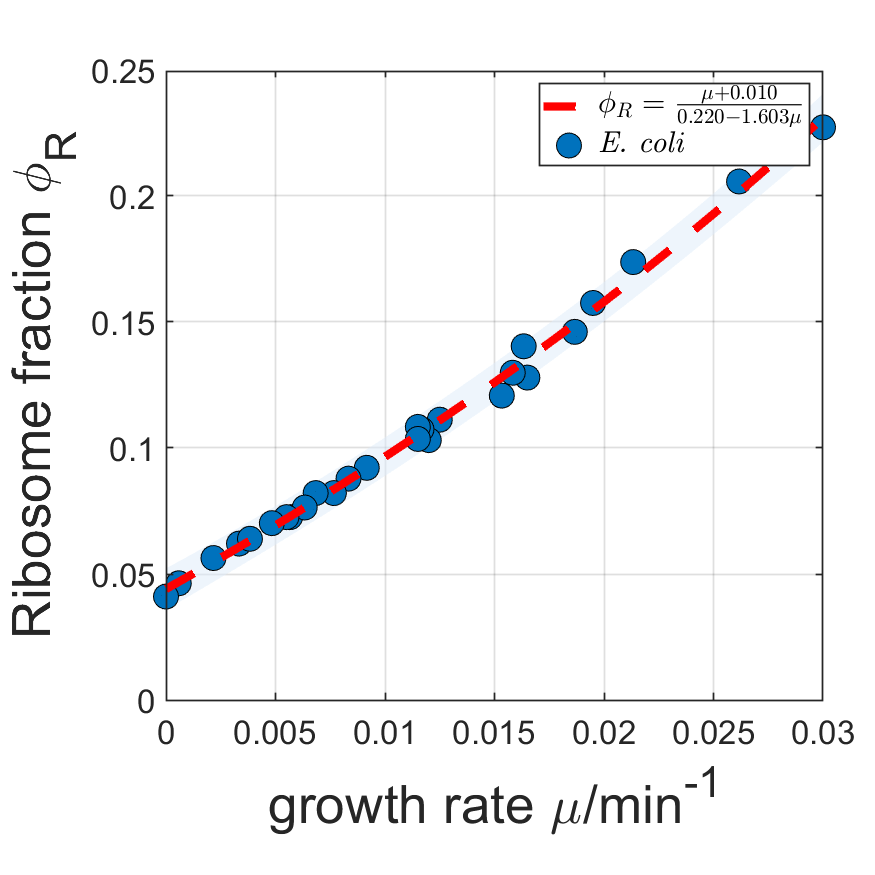

A=xlsread('Dai2016.xls'); 

mu=A(:,1)/60;%min-1
phiR=A(:,2);

%fit model to data.
[xData, yData] = prepareCurveData( mu, phiR );

ft = fittype( '(x+c1)/(c2*x+c3)', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.964888535199277 0.157613081677548 0.970592781760616];

[fitresult, gof] = fit( xData, yData, ft, opts );
temp1=coeffvalues(fitresult);
c1=temp1(1);
c2=temp1(2);
c3=temp1(3);

%plot 
fig=figure;
set(fig,'Position',[300 100 700 700]);

ax1=axes('position', [0.19 0.2 0.75 0.72]);
temp1=[0:0.001:0.03]';
intv=predint(fitresult,temp1);
fill([temp1',fliplr(temp1')],[intv(:,1)',fliplr(intv(:,2)')], ...
    [0.8706 0.9216 0.9804], ...
    "EdgeAlpha",0, ...
    "FaceAlpha",0.5);
hold on
p=plot(xData, yData,"o","MarkerSize",15, ...
    "MarkerEdgeColor","black", ...
    "MarkerFaceColor",'#0072BD', ...
    'DisplayName','{\it E. coli}');
hold on
h = plot([0:0.001:0.03],[fitresult(0:0.001:0.03)],"--","LineWidth",5, ...
    "Color","red",...
    'DisplayName',['$\phi_R=\frac{\mu+',num2str(c1,'%.3f'),'}{',num2str(c3,'%.3f'),num2str(c2,'%.3f'),'\mu}$']);
legend([h,p],'Interpreter',"latex");



set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
xlabel('growth rate \mu/min^{-1}','interpreter','tex','FontSize',32);
ylabel('Ribosome fraction \phi_R','interpreter','tex','FontSize',32);
box on
grid on
hold off

%find minimum of the multivariable function
mR=8.07e5;
alphaR=0;%min-1
alpha_phi=0;%min-1
syms phi0 k_chi kR C1 C2 C3
eq2=C1==(k_chi*phi0+mR*alpha_phi)/mR;
eq3=C2==(kR-k_chi)/kR;
eq4=C3==((kR*alpha_phi-alphaR*k_chi)*mR+kR*k_chi)/(kR*mR);


[phi0,k_chi,kR]=solve([eq2,eq3,eq4],phi0,k_chi,kR);
temp1=confint(fitresult);
c1_int=temp1(2,1)-c1;
c2_int=temp1(2,2)-c2;
c3_int=temp1(2,3)-c3;

temp1=fun_trans(phi0);
temp2=fun_trans(-phi0);
temp3=fmincon(temp1,[c1,c2,c3], ...
                 [],[],[],[], ...
                 [c1-c1_int,c2-c2_int,c3-c3_int], ...
                 [c1+c1_int,c2+c2_int,c3+c3_int]);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


temp4=fmincon(temp2,[c1,c2,c3], ...
                 [],[],[],[], ...
                 [c1-c1_int,c2-c2_int,c3-c3_int], ...
                 [c1+c1_int,c2+c2_int,c3+c3_int]);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


phi0_min=temp1(temp3)

phi0_min = 0.0310

phi0_max=temp1(temp4)

phi0_max = 0.0610

phi0=temp1([c1,c2,c3])

phi0 = 0.0440

uncer_phi0=(phi0_max-phi0_min)/phi0

uncer_phi0 = 0.6806


temp1=fun_trans(kR);
temp2=fun_trans(-kR);
temp3=fmincon(temp1,[c1,c2,c3], ...
                 [],[],[],[], ...
                 [c1-c1_int,c2-c2_int,c3-c3_int], ...
                 [c1+c1_int,c2+c2_int,c3+c3_int]);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


temp4=fmincon(temp2,[c1,c2,c3], ...
                 [],[],[],[], ...
                 [c1-c1_int,c2-c2_int,c3-c3_int], ...
                 [c1+c1_int,c2+c2_int,c3+c3_int]);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


kR_min=temp1(temp3)%min-1

kR_min = 4.5365e+04

kR_max=temp1(temp4)%min-1

kR_max = 1.1085e+05

kR=temp1([c1,c2,c3])%min-1

kR = 6.8161e+04

uncer_kR=(kR_max-kR_min)/kR

uncer_kR = 0.9608


temp1=fun_trans(k_chi);
temp2=fun_trans(-k_chi);
temp3=fmincon(temp1,[c1,c2,c3], ...
                 [],[],[],[], ...
                 [c1-c1_int,c2-c2_int,c3-c3_int], ...
                 [c1+c1_int,c2+c2_int,c3+c3_int]);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


temp4=fmincon(temp2,[c1,c2,c3], ...
                 [],[],[],[], ...
                 [c1-c1_int,c2-c2_int,c3-c3_int], ...
                 [c1+c1_int,c2+c2_int,c3+c3_int]);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


k_chi_min=temp1(temp3)%min-1

k_chi_min = 1.5399e+05

k_chi_max=temp1(temp4)%min-1

k_chi_max = 2.0091e+05

k_chi=temp1([c1,c2,c3])%min-1

k_chi = 1.7745e+05

uncer_k_chi=(k_chi_max-k_chi_min)/k_chi%h-1

uncer_k_chi = 0.2645



r_2=gof.adjrsquare

r_2 = 0.9940

rmse=gof.rmse

rmse = 0.0036

writematrix([mR,alphaR,alpha_phi, ...
             kR,kR_min,kR_max,uncer_kR, ...
             k_chi,k_chi_min,k_chi_max,uncer_k_chi, ...
             phi0,phi0_min,phi0_max,uncer_phi0, ...
             c1,c1_int,c2,c2_int,c3,c3_int, ...
             r_2,rmse], ...
            "Dai_para.csv")

Character-to-function transform function.

function [res]= fun_trans(sym0)


temp1=matlabFunction(sym0);
temp2=char(temp1);
if contains(temp2,"C2")
temp2=strrep(temp2,'C2,C3','C');
temp2=strrep(temp2,'C2','C(2)');
temp2=strrep(temp2,'C3','C(3)');
elseif contains(temp2,"C1")
temp2=strrep(temp2,'C1,C3','C'); 
temp2=strrep(temp2,'C1','C(1)');
temp2=strrep(temp2,'C3','C(3)');
else
temp2=strrep(temp2,'(C3)','(C)'); 
temp2=strrep(temp2,'C3','C(3)');   
end

res=str2func(temp2);


end
